clear; close all; clc;

Punkty_startowe = [[3.5; 0], [2.5; -2], [0.5; -2], [0.5; 0]];


Obliczenia gradientu i hesjanu na potrzeby metod optymalizacji

syms x1 x2;
f = (1 - x1 + 1.5)^2 + 100 * (x2 + 1 - (x1 - 1.5)^2)^2;
grad = gradient(f);
hessian = hessian(f, [x1, x2]);
f_num = matlabFunction(f);
disp(simplify(grad));

$$\left(\begin{array}{c} 2\,x_{1}-200\,\left(2\,x_{1}-3\right)\,\left(x_{2}-{\left(x_{1}-\frac{3}{2}\right)}^{2}+1\right)-5\\ 200\,x_{2}-200\,{\left(x_{1}-\frac{3}{2}\right)}^{2}+200 \end{array}\right)$$

disp(simplify(hessian));

$$\left(\begin{array}{cc} 1200\,{x_{1}}^{2}-3600\,x_{1}-400\,x_{2}+2302 & 600-400\,x_{1}\\ 600-400\,x_{1} & 200 \end{array}\right)$$

Wizualizacja funkcji:

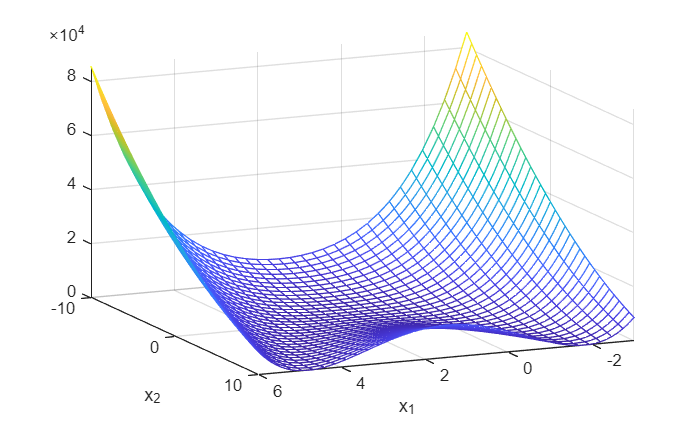

fmesh(f, [-3 6 -10 10]);
xlabel('x_1');
ylabel('x_2');

view([156 20]);

Obliczenia optymalnej wartości metodą Quasi - Newtona z gradientem przybliżonym numerycznie

% Set nondefault solver options
options = optimoptions("fminunc",'Algorithm', 'quasi-newton', "OutputFcn", @outputFun);

%Plots
[x1, x2] = meshgrid(-1:0.1:4, -3:0.1:3);
Z = f_num(x1, x2);

Wykresy poziomicowe ruchu algorytmu

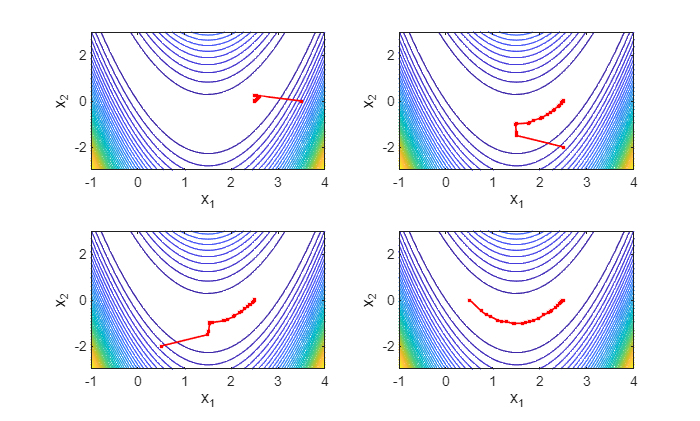


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.



figure;

for i = 1:1:4
    x0 = Punkty_startowe(:, i);
    [solution,objectiveValue, exitFlag, output] = fminunc(@Rosenbrock, x0, options);
    subplot(2,2,i);
    contour(x1, x2, Z, 40);
    hold on;
    plot(history_x(:,1), history_x(:,2), "-r.", "LineWidth", 1);
    xlabel("x_1");
    ylabel("x_2");
    hold off;
    sol(1:2, i) = solution;
end

Zapis danych do pozostałych wykresów

s.a = history_f;
fun_count(1) = output.funcCount;

Obliczenia optymalnej wartości z wykorzystaniem metody Quasi - Newtona z podanym wzorem gradientu:

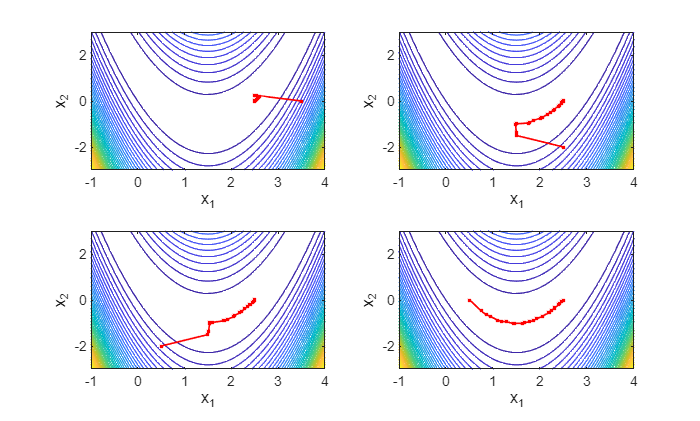


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.



options = optimoptions("fminunc",'Algorithm', 'quasi-newton', ...
    'SpecifyObjectiveGradient',true, "OutputFcn", @outputFun);

figure;

for i = 1:1:4
    x0 = Punkty_startowe(:, i);
    [solution,objectiveValue, exitFlag, output] = fminunc(@Rosenbrock, x0, options);
    subplot(2,2,i);
    contour(x1, x2, Z, 40);
    hold on;
    plot(history_x(:,1), history_x(:,2), "-r.", "LineWidth", 1);
    xlabel("x_1");
    ylabel("x_2");
    hold off;
    sol(1:2, i+4) = solution;
end

s.b = history_f;
fun_count(2) = output.funcCount;

Obliczenia optymalnej wartości z wykrozystaniem metody Trust Region:

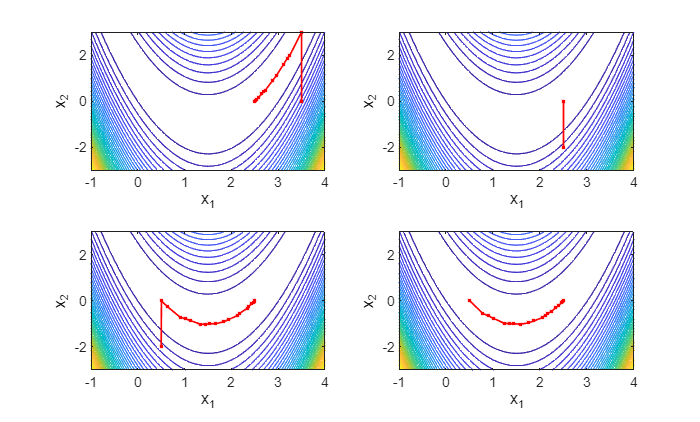


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the value of the function tolerance.



options = optimoptions("fminunc",'Algorithm','trust-region', ...
    'SpecifyObjectiveGradient',true, "OutputFcn", @outputFun);

figure;

for i = 1:1:4
    x0 = Punkty_startowe(:, i);
    [solution,objectiveValue, exitFlag, output] = fminunc(@Rosenbrock, x0, options);
    subplot(2,2,i);
    contour(x1, x2, Z, 40);
    hold on;
    plot(history_x(:,1), history_x(:,2), "-r.", "LineWidth", 1);
    xlabel("x_1");
    ylabel("x_2");
    hold off;
    sol(1:2, i+8) = solution;
end

s.c = history_f;
fun_count(3) = output.funcCount;
sol(1:2, 3) = solution;

Obliczenia optymalnej wartości z wykrozystaniem metody Trust Region z podanym Hesjanem:

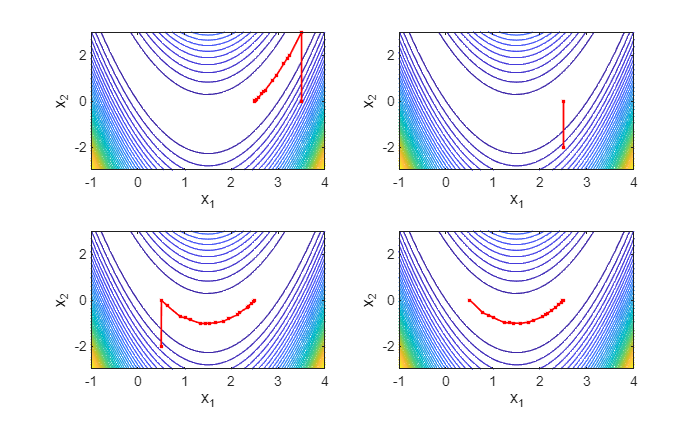


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.


Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the value of the function tolerance.



options = optimoptions("fminunc",'Algorithm','trust-region', ...
    'SpecifyObjectiveGradient',true, 'HessianFcn', 'objective', "OutputFcn", @outputFun);

figure;

for i = 1:1:4
    x0 = Punkty_startowe(:, i);
    [solution,objectiveValue, exitFlag, output] = fminunc(@Rosenbrock, x0, options);
    subplot(2,2,i);
    contour(x1, x2, Z, 40);
    hold on;
    plot(history_x(:,1), history_x(:,2), "-r.", "LineWidth", 1);
    xlabel("x_1");
    ylabel("x_2");
    hold off;
    sol(1:2, i+12) = solution;
end

s.d = history_f;
fun_count(4) = output.funcCount;
sol(1:2, 4) = solution;

Pozostałe wykresy

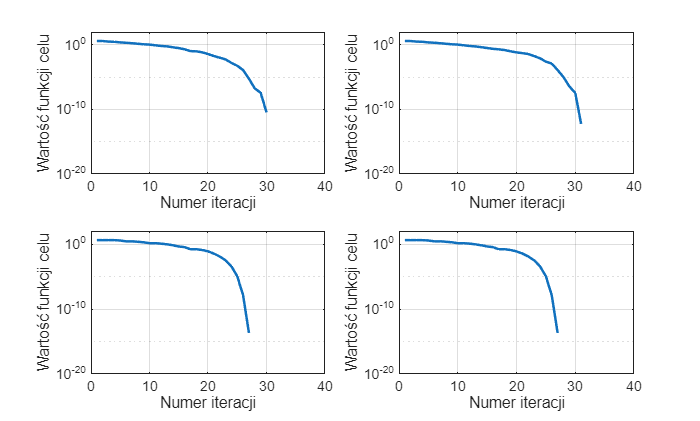

figure;
subplot(2,2,1);
x = 1:1:length(s.a);
semilogy(x, s.a, "LineWidth", 1.5);
grid on;
xlim([0 40]);
ylim([1e-20 100]);
xlabel("Numer iteracji");
ylabel("Wartość funkcji celu");
subplot(2,2,2);
x = 1:1:length(s.b);
semilogy(x, s.b, "LineWidth", 1.5);
grid on;
xlim([0 40]);
ylim([1e-20 100]);
xlabel("Numer iteracji");
ylabel("Wartość funkcji celu");
subplot(2,2,3);
x = 1:1:length(s.c);
semilogy(x, s.c, "LineWidth", 1.5);
grid on;
xlim([0 40]);
ylim([1e-20 100]);
xlabel("Numer iteracji");
ylabel("Wartość funkcji celu");
subplot(2,2,4);
x = 1:1:length(s.d);
semilogy(x, s.d, "LineWidth", 1.5);
grid on;
xlim([0 40]);
ylim([1e-20 100]);
xlabel("Numer iteracji");
ylabel("Wartość funkcji celu");

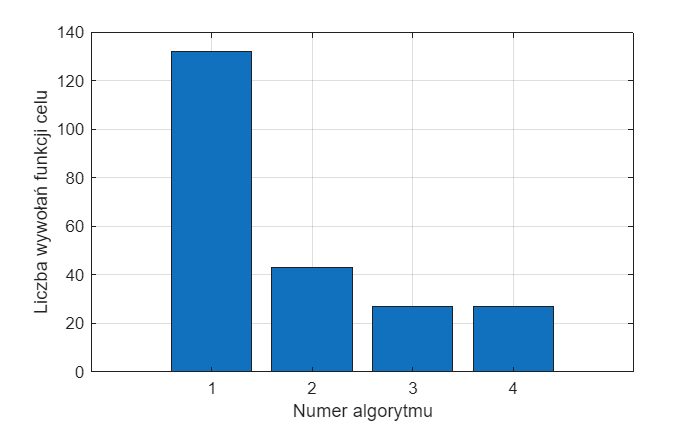

figure;
bar(fun_count);
grid on;
ylabel("Liczba wywołań funkcji celu");
xlabel("Numer algorytmu");